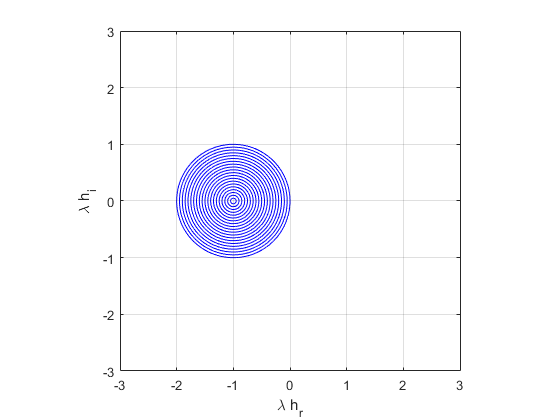

i=sqrt(-1);
% Specify real range and number of points
lhr0=-3;
lhr1=3;
Nr = 1024;
% Specify imaginary range and number of points
lhi0=-3;
lhi1=3;
Ni = 1024;
% Construct mesh
lhr = linspace(lhr0,lhr1,Nr);
lhi = linspace(lhi0,lhi1,Ni);
[x,y] = meshgrid(lhr,lhr);
% Calculate lh
lh=x+i*y;
% amplification factor of Forward Euler
theta=1+lh;
% Plot contours of magnitude(theta)=1
contour(x,y,abs(theta),[0:0.05:1],'b-');
axis([lhr0,lhr1,lhi0,lhi1]);
axis('square');
xlabel('\lambda h_r');
ylabel('\lambda h_i');
grid on